% Define vehicle properties
m = 1.0;
g = 9.81;
r = 0.1;
I = 0.1;

% Current State Along Trajectory
x0 = [0,0,0,0,0,0];
u0 = (m * g / 2) * [1,1];

[A, B] = getLinearization(x0, u0, m, I, r);

C = eye(6);
Q = eye(6);
R = eye(2);

sys = ss(A, B, C, 0);

% Compute LQR gain
K = lqr(sys, Q, R);

% Get eigenvalues of autonomous system
eig((A - B * k))

ans =   -3.7217 + 0.0000i
  -0.3449 + 2.4935i
  -0.3449 - 2.4935i
  -0.5883 + 0.0000i
  -1.0987 + 0.4551i
  -1.0987 - 0.4551i


A_aug = A - B * K;
Q = eye(6);

P = lyap(A_aug, Q);

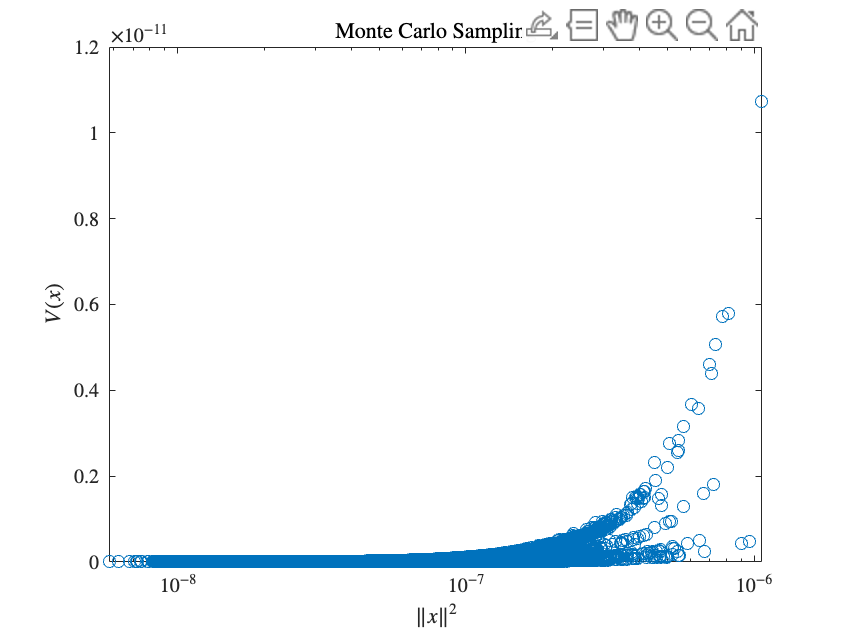

f_nl = @(x) [
    x(2);
    -((u0(1)-K(1,:)*x) + (u0(2)-K(2,:)*x)) * sin(x(5)) / m;
    x(4);
    ((u0(1)-K(1,:)*x) + (u0(2)-K(2,:)*x)) * cos(x(5)) / m - g;
    x(6);
    r * ((u0(1)-K(1,:)*x) - (u0(2)-K(2,:)*x)) / I];

% Functions to check stability conditions
V = @(x) x' * P * x;
Vdot = @(x) (2 * x' * P) * f_nl(x);

% Monte Carlo Sampling Parameters
N = 100000;
x = lognrnd(log(1e-8), 1, [6, N]);

V_arr = zeros(1, N);
Vdot_arr = zeros(1, N);
norm_arr = zeros(1, N);

for i = 1:N
    V_arr(i) = V(x(:,i));
    Vdot_arr(i) = Vdot(x(:,i));
    norm_arr(i) = norm(x(:,i));
end

[norm_arr, idx] = sort(norm_arr);

V_arr = V_arr(idx);
Vdot_arr = Vdot_arr(idx);

figure
semilogx(norm_arr, V_arr, 'o')
title('Monte Carlo Sampling')
xlabel('$\| x \|^2$')
ylabel('$V(x)$')

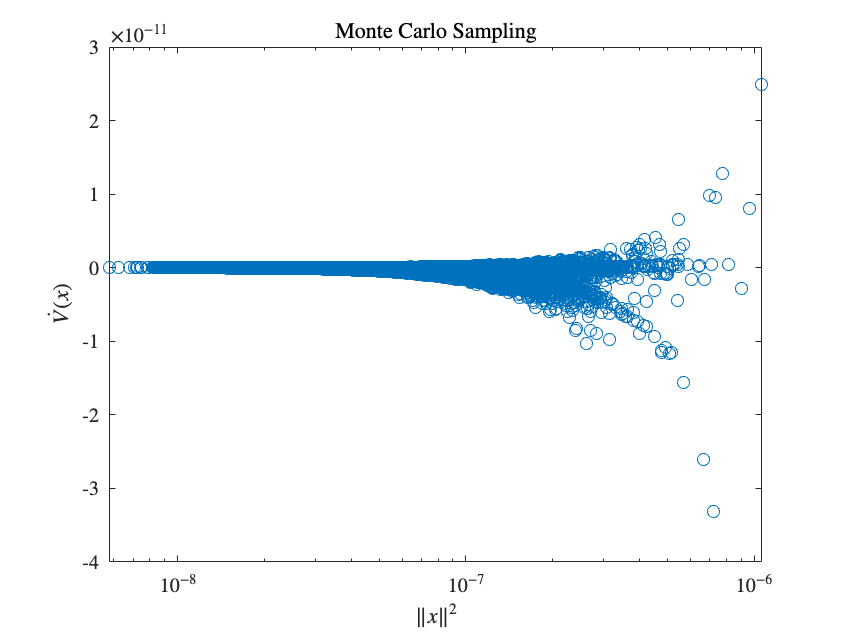


figure
semilogx(norm_arr, Vdot_arr, 'o')
title('Monte Carlo Sampling')
xlabel('$\| x \|^2$')
ylabel('$\dot{V}(x)$')

% Define simulation parameters
T = 100;
dt = 0.0001;
t = 0:dt:T;

xnl = zeros(6, length(t));

% Current State Along Trajectory
xref = [0,0,0,0,0,0]';
uref = (m * g / 2) * [1,1];

% Perturbed Initial Condition
x0 = 1 * [1, 1, 1, 1, 1, 1];
xnl(:,1) = x0;

for i = 1:length(t) - 1

    xe = xnl(:,i) - xref;

    u = uref - k * xe;

    xcur = xnl(:,i);

    xdot = [xcur(2);
            -(u(1) + u(2)) * sin(xcur(5)) / m;
            xcur(4);
            (u(1) + u(2)) * cos(xcur(5)) / m - g;
            xcur(6);
            r*(u(1) - u(2)) / I];

    xnl(:,i+1) = xnl(:,i) + xdot * dt;
end
